A1 = [1, -0.8];
A2 = [1, 0.8];
n = 0 : 19;

a_x = [0, 0.75, zeros(1, 7), -0.5, zeros(1, 10)];
x_20 = ifft(a_x) * length(a_x);

y1_20 = filter(1, A1, x_20);
y2_20 = filter(1, A2, x_20);

a_y1 = fft(y1_20) / length(y1_20);
a_y2 = fft(y2_20) / length(y2_20);

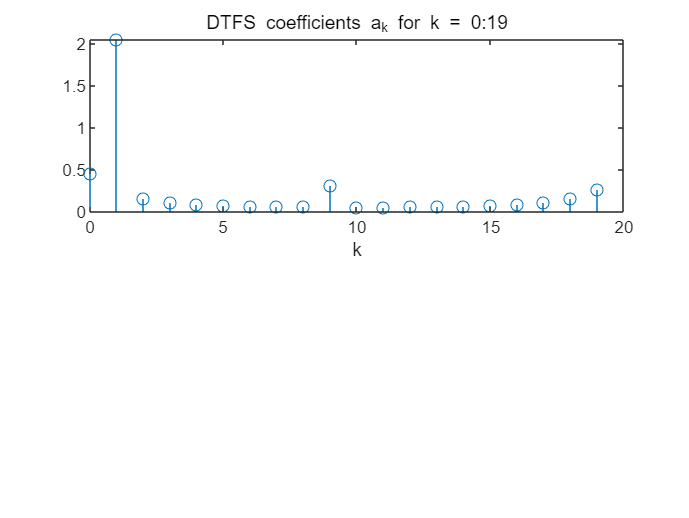

subplot(2, 1, 1);
stem(n, abs(a_y1));
xlabel("k");
title('DTFS coefficients a_k for k = 0:19');

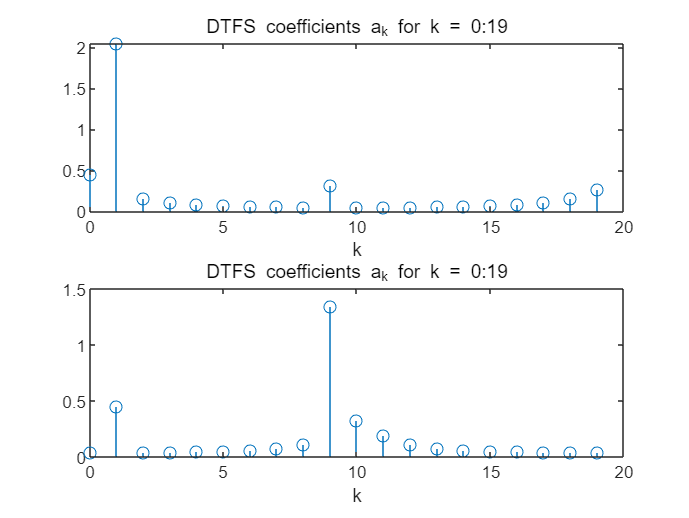

subplot(2, 1, 2);
stem(n, abs(a_y2));
xlabel("k");
title('DTFS coefficients a_k for k = 0:19');